# **A surprising feature of diffraction and magnification**

**Related to Question 14 on Homework 1**

We explore the impact of f/# and focal length on image magnification and diffraction-related blur.

We create a scene that is a line and compute the line spread.  Keeping the f/# fixed, we double the focal length and recompute.

- How does changing the focal length (but retaining the f/#) impact the line spread?

- How does changing the focal length (but retaining the f/#) impact the height of the line (magnification)?

From these two slides in class we see that the diffraction limited point spread depends only on the f/#, not the focal length.  

But the magnification depends on the focal length.  Read to the end to see how this can be.

#### 
$$M=\frac{d_I }{d_O }$$


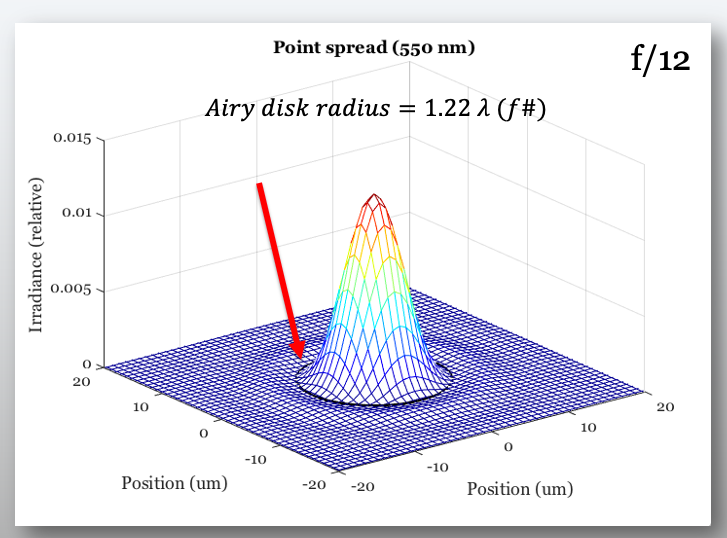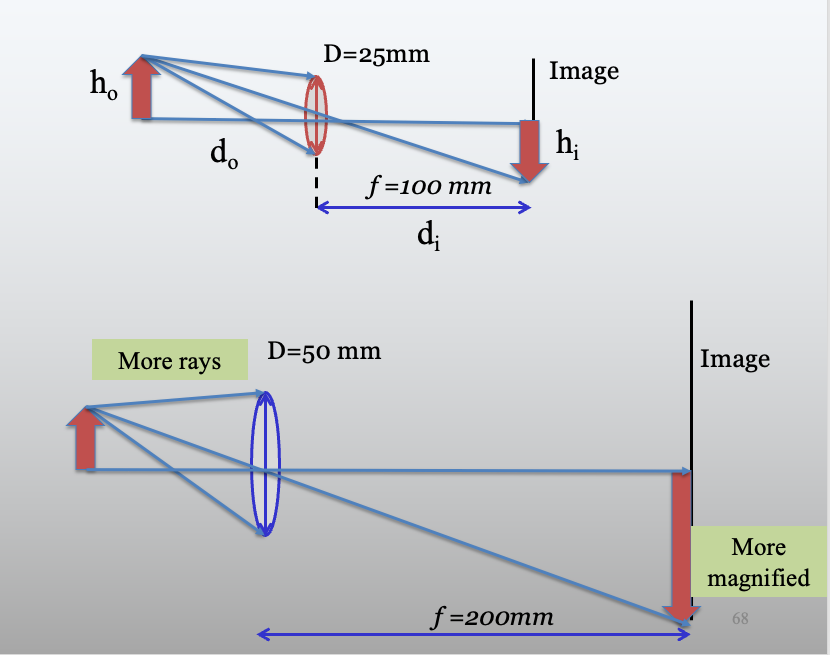

% Initialize ISETCam
ieInit;

## Create a thin line scene

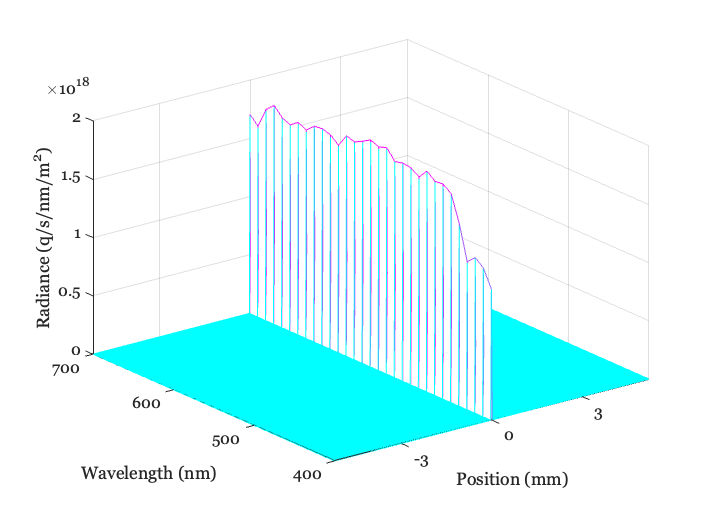

% High resolution line.
scene = sceneCreate('line',512);

% To make sure its spatial sampling is relatively fine, set the field
% of view to be small, say half a degree.
scene = sceneSet(scene,'fov',0.5);

% Plot position is (x,y)
scenePlot(scene,'radiance hline',round([1 sceneGet(scene,'rows')/2]));

## Create an optical image

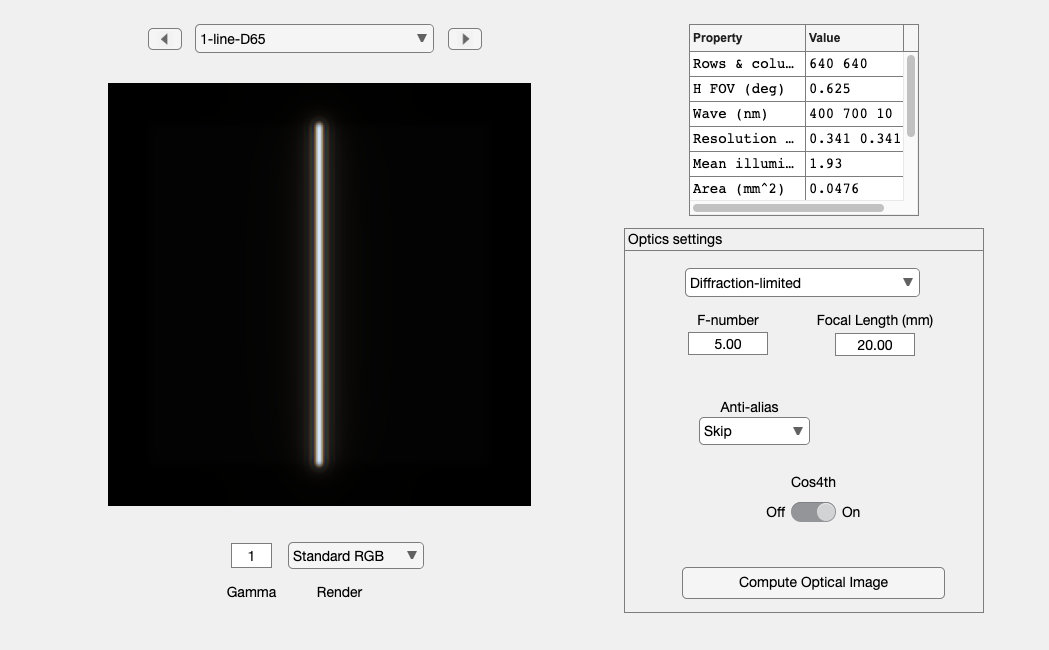

oi = oiCreate;
oi = oiSet(oi,'optics fnumber',5);

fLength = 0.02;
oi = oiSet(oi,'optics focal length',fLength);  % 20 millimeters

oi = oiCompute(oi,scene);

% Have a look
oiWindow(oi);

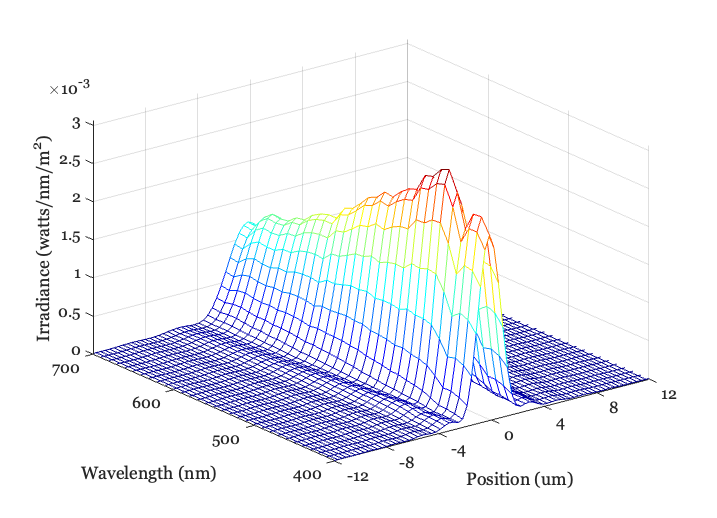


% Plot the irradiance (units of photons) across a horizontal line
oiPlot(oi,'irradiance energy hline ',round([1,oiGet(oi,'rows')/2]));

set(gca,'xlim',[-12 12],'xtick',(-12:4:12));

## Double the focal length, keeping the f-number

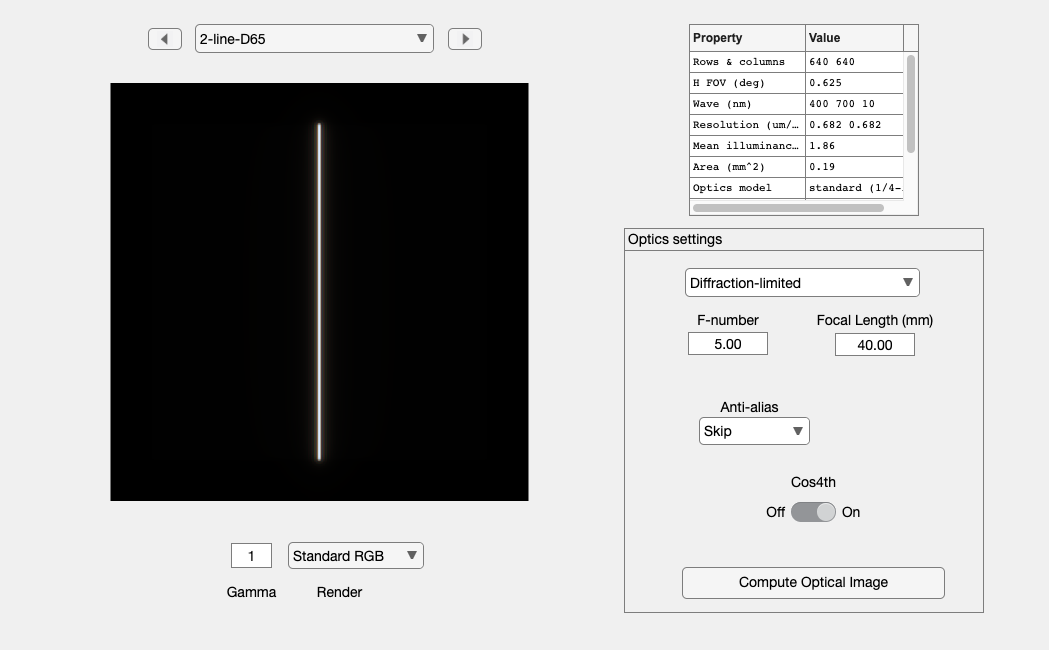

% Increas the focal length, but the same f-number
oi2 = oiSet(oi,'optics focal length',2*fLength);
oi2 = oiSet(oi2,'optics fnumber',5);

oi2 = oiCompute(oi2,scene);
oiWindow(oi2);

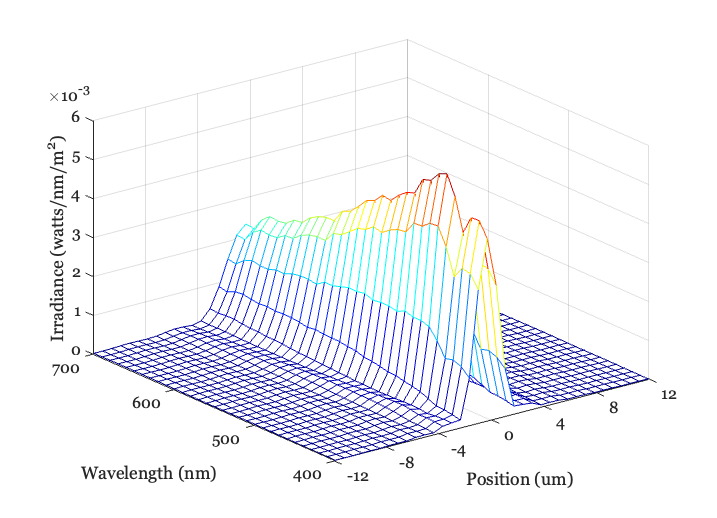


oiPlot(oi2,'irradiance energy hline ',round([1, oiGet(oi2,'rows')/2]));
set(gca,'xlim',[-12 12],'xtick',(-12:4:12));

### **With a fixed f/#, the linespread, like the point spread, is unchanged even though we have changed the focal length.**

## What about the magnification?

% The height of the line changes, showing the magnification

l1 = oiGet(oi,'height','mm');
l2 = oiGet(oi2,'height','mm');

fprintf('The short focal length line height:  %f mm\n',l1);

The short focal length line height:  0.218168 mm


fprintf('The short focal length line height:  %f mm\n',l2);

The short focal length line height:  0.436335 mm


### The increase in the focal length does magnify the image

## Why?  The magic of the f/#

The focal length increases the magnification.  But maintaining the f/# means we must increase the aperture, and this reduces the diffraction blur.  The increase in aperture perfectly compensates for the increase in magnification.  The blur size remains the same.

Once again, the f/#  (or numerical aperture) is a critical variable. 